**Load the necessary Modules**

clear all
clc
mrstModule add ad-core ad-blackoil ad-eor ad-props incomp mrst-gui %load necessary modules
mrstModule list % List the loaded modules

Currently active MRST modules
  * mrst-gui
  * incomp
  * ad-props
  * ad-eor
  * ad-blackoil
  * ad-core


**Set Up the Geometry**

H (rock depth) = 0.2m,    Nz (Points of the spatial Grid) = 100

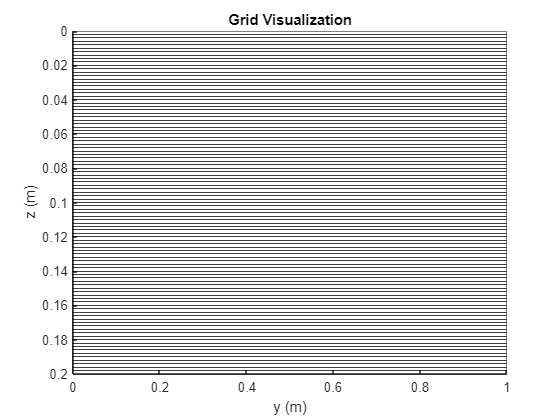

% Step 1: Define the Grid
Nx = 1; % Number of grid cells in the x-direction
Ny = 1; % Number of grid cells in the y-direction
Nz = 100; % Number of grid cells in the z-direction
H = 0.2; % Rock depth (in the z-direction)
Lx = 1; % Length of the domain (in the x-direction)
Ly = 1; % Length of the domain (in the x-direction)
% depth = linspace(0, H, Nz)';
G = cartGrid([Nx, Ny, Nz], [Lx, Ly, H]); % Grid with dimensions [Nx, Ny, Nz] in x-y-z plane

G = computeGeometry(G); % Compute geometry (cell volumes, centroids, face areas, etc.)


% Plot the grid
plotGrid(G,'FaceColor','none','FaceAlpha',.2,'EdgeAlpha',.5);view(90,0);
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');
title('Grid Visualization');

**Define Rock and Fluid properties**

*Rock Properties:*

$\varphi_0 =0.3$,    $K_0 =0.02\textrm{∙}{10}^{-12} \ m^2$

*Fluid Properties:*

$\mu_w =\mu_o =0.001\ Pa\textrm{∙}s$,    $\rho_w =1000\frac{kg}{m^3 }$,    $\rho_o =660\frac{kg}{m^3 }$,    $k_{rw}^0 =k_{ro}^0 =1$,    $a=b=4$,    $S_{wr} =S_{or} =0.001$

% Step 2: Define Fluid and Rock Properties
perm = repmat(0.02e-12, G.cells.num, 1); % Define initial absolute permeability
poro = 0.3; % Define porosity
rock = makeRock(G,perm,poro); %define intial absolute permeability and porosity
% plotCellData(G,rock.perm); view(3);

fluid = initSimpleADIFluid('phases', 'WO', ...          %Fluid phases: Water, Oil
                           'mu', [0.001, 0.001], ...    %Viscosities [Pa*s]
                           'rho', [1000, 660], ...      %Densities [kg/m^3]
                           'n', [4, 4], ...             %Monomials
                           'smin', [0.001, 0.001]);     %Irreducible Water Saturation and Residual Oil Saturation

*Capillary Pressure:*

$p_c =b_w \textrm{∙}{{\left(S+\varepsilon_1 \right)}}^{-a_w } +b_o \textrm{∙}{{\left(1-S+\varepsilon_2 \right)}}^{-a_o }$,    *N.B. It is defined as an anonymous function of the saturation in the fluid object*

$b_w =500$,    $b_o =-500$,    $a_w =a_o =0.5$

% Define capillary pressure equation parameters
a_w = 0.5; % Pore size distribution index for imbibition
a_o = 0.5; % Pore size distribution index for drainage
b_w = 500; % Constant for entry pressure for imbibition
b_o = -500; % Constant for entry pressure for drainage

% fluid.pcOW = @(s, varargin) b_w.*(max(0, min(1, (s-sl)/(su-sl) )) + eps(10)).^-a_w +b_o.*(1 -max(0, min(1, (s-sl)/(su-sl))) +eps(10)).^-a_o;
% fluid.pcOW = @(s, varargin) b_w.*(s + eps(10)).^-a_w +b_o.*(1 - s +eps(10)).^-a_o;
% fluid.pcOW = @(s, varargin) b_w.*(max(0, min(1, (s - fluid.krPts.w)./(1 - fluid.krPts.o - fluid.krPts.w))) + eps(10)).^-a_w +b_o.*(1 - max(0, min(1, (s - fluid.krPts.w)./(1 - fluid.krPts.o - fluid.krPts.o))) + eps(10)).^-a_o;
disp(fluid.krPts.o(1))

   1.0000e-03



fluid.pcOW = @(s, varargin) b_w.*((s - fluid.krPts.w(1))/(1 - fluid.krPts.o(1) - fluid.krPts.o(1)) + eps(10)).^-a_w +b_o.*(1 - (s - fluid.krPts.w(1))/(1 - fluid.krPts.o(1) - fluid.krPts.o(1)) + eps(10)).^-a_o;

disp(fluid);

    rhoWS: 1000
       bW: @(p,varargin)b*constantReciprocalFVF(p,varargin{:})
      muW: @(p,varargin)constantViscosity(opt.mu(i),p,varargin{:})
      krW: @(s,varargin)max(0,min(1,(s-sl)/(su-sl))).^opt.n(i)
    krPts: [1×1 struct]
    rhoOS: 660
       bO: @(p,varargin)b*constantReciprocalFVF(p,varargin{:})
      muO: @(p,varargin)constantViscosity(opt.mu(i),p,varargin{:})
      krO: @(s,varargin)max(0,min(1,(s-sl)/(su-sl))).^opt.n(i)
     pcOW: @(s,varargin)b_w.*((s-fluid.krPts.w(1))/(1-fluid.krPts.o(1)-fluid.krPts.o(1))+eps(10)).^-a_w+b_o.*(1-(s-fluid.krPts.w(1))/(1-fluid.krPts.o(1)-fluid.krPts.o(1))+eps(10)).^-a_o



**Set up the model**

The model object contains the grid, the fluid and rock properties and the modeling equations.

gravity reset on;
model = OilWaterNanoparticlesModel(G,rock,fluid);

% Prepare the model for simulation
model = model.validateModel();

% Inspect model
disp(model);

  OilWaterNanoparticlesModel with properties:

                    polymer: 0
                 surfactant: 1
                 usingShear: 0
              usingShearLog: 0
        usingShearLogshrate: 0
                     disgas: 0
                     vapoil: 0
                  drsMaxRel: Inf
                  drsMaxAbs: Inf
                      fluid: [1×1 struct]
                       rock: [1×1 struct]
                   dpMaxRel: Inf
                   dpMaxAbs: Inf
                   dsMaxAbs: 0.2000
            maximumPressure: Inf
            minimumPressure: -Inf
                      water: 1
                        gas: 0
                        oil: 1
          useCNVConvergence: 1
               toleranceCNV: 1.0000e-03
                toleranceMB: 1.0000e-07
                  inputdata: []
           extraStateOutput: 0
         extraWellSolOutput: 1
               outputFluxes: 1
     

% %Inspect state functions
% model.setupStateFunctionGroupings();
% disp(model.PVTPropertyFunctions);
% disp(model.FlowPropertyFunctions);
% disp(model.FlowDiscretization);
% plotStateFunctionGroupings(model.PVTPropertyFunctions);
% plotStateFunctionGroupings(model.FlowPropertyFunctions);
% plotStateFunctionGroupings(model.FlowDiscretization);

**Set up Initial and Boundary Conditions**

*Initial Conditions:*

$S_W =S_w^0 \ at\ t=0,\ \ \ \ 0\le z\le H$,    $S_w^0 =0.27$, $S_o^0 =1-S_w^0 =0.73$


$$c=0\ at\ t=0,\ \ \ \ 0\le z\le H$$



$$c_{s1} =c_{s2} =0\ at\ t=0,\ \ \ 0\le z\le H$$


*Boundary Conditions:*


$$S_w =1-S_o^0 ,\ c=c_0 ,\ c_{s1} =c_{s2} =0\ at\ t>0\;\textrm{and}\ z=0,$$
    
$$\left.\left.\left.\left.c_0 =a\right)0.0\frac{m^3 }{m^3 },b\right)\ 0.0009\frac{m^3 }{m^3 },c\right)\ 0.004\frac{m^3 }{m^3 },d\right)\ 0.01\frac{m^3 }{m^3 }$$


                                                                                        
$$S_o^0 =1-S_w^0 =0.73$$


$\frac{dS_w }{dz}=\frac{dc}{dz}=\frac{dc_{s1} }{dz}=\frac{dc_{s2} }{dz}=0\ at\ t>0\;\textrm{and}\;z=H,$    *no-flow boundary condition

% Set up the initial state

% Constant pressure, residual water saturation, no surfactant
% pcOW = fluid.pcOW;
% pcOW = 387.05 Pa calculated analytically for t=0
% I initialize the reservoir state according to hydrostatic equilibrium, which
% is straightforward to compute, assuming that the overlying pressure is caused by a column of fluids 
% with a density equal to the difference in density of the two fluids in the reservoir
state0 = initResSol(G, G.cells.centroids(:,3)*(fluid.rhoWS - fluid.rhoOS)*norm(gravity), [ 0.27, 0.73]); 
state0.cs    = zeros(G.cells.num, 1);
state0.csmax = state0.cs;
state0.cs1   = state0.cs;
state0.cs2   = state0.cs;

% Prepare state for simulation
state0 = model.validateState(state0);

% Inspect the fluid properties graphically
% inspectFluidModel(model,'field','Densities');

% Set up boundary conditions
bc = fluxside([], G, 'zmax', 0, 'sat', [0.27, 0.73]); % you can use either 'lower', 'zmax'or 'bottom'
bc = pside(bc, G, 'zmin', 378.05, 'sat', [0.27, 0.73]); %% you can use either 'upper', 'zmin'or 'top'
% the cs,cs1,cs2 should only apply to the upper/top boundary
bc.cs = [0, 0.004]; bc.cs1 = [0,0]; bc.cs2 = [0,0];

**Define simulation schedule and set solver parameters**

dt=Adaptive time step

t_inf=2 hr,1 day,10 days,20 days,40 days,80 days

% Schedule: describing time intervals and corresponding drive mechanisms
simTime = 40*day;
% %rumpump time scheduling
% nstep   = 5;
% timesteps = rampupTimesteps(simTime,simTime/(nstep + 1),2);
% schedule = simpleSchedule(timesteps, 'bc', bc);
% linspace time scheduling
schedule = simpleSchedule(diff(linspace(0,simTime,40)), 'bc', bc);
schedule = model.validateSchedule(schedule);


% Determine the best solver to use for the model
solver = getNonLinearSolver(model);
disp(solver);

  NonLinearSolver with properties:

                 maxIterations: 25
                 minIterations: 1
               maxTimestepCuts: 6
                  LinearSolver: [1×1 BackslashSolverAD]
                       verbose: 0
                   reportLevel: 0
                    identifier: ''
              timeStepSelector: [1×1 IterationCountTimeStepSelector]
                 useRelaxation: 0
           relaxationParameter: 1
                relaxationType: 'dampen'
           relaxationIncrement: 0.1000
           relaxationDecrement: []
                 minRelaxation: 0.5000
                 maxRelaxation: 1
          oscillationThreshold: 1
                 useLinesearch: 0
        alwaysUseStabilization: 0
     linesearchReductionFactor: 0.5000
      linesearchDecreaseFactor: 1
       linesearchMaxIterations: 10
    linesearchConvergenceNames: {}
     linesearchResidualScaling: []
         linesearchReduct

**Run and monitor simulation**

% Setup a function which does some plotting after every timestep
fn = getPlotAfterStep(state0, model, schedule, 'view',[90 0], ...
'plotWell', false, 'plotReservoir', true, 'field', 's:1') %, ...'plot1d', true);

fn = function_handle with value:
    @(model,states,reports,solver,schedule,simtime)afterStepFunction(model,states,reports,solver,schedule,simtime,injData,injectWell,hdata,hwell)


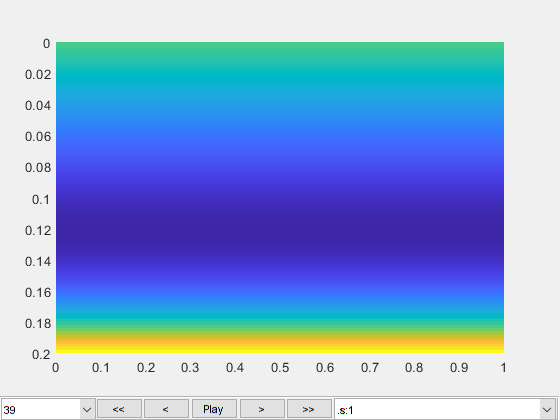

Solving timestep 01/39:         -> 1 Day, 2215 Seconds, 384.62 Milliseconds
Solving timestep 02/39: 1 Day, 2215 Seconds, 384.62 Milliseconds -> 2 Days, 1 Hour, 830.77 Seconds
Solving timestep 03/39: 2 Days, 1 Hour, 830.77 Seconds -> 3 Days, 1 Hour, 3046.15 Seconds
Solving timestep 04/39: 3 Days, 1 Hour, 3046.15 Seconds -> 4 Days, 2 Hours, 1661.54 Seconds
Solving timestep 05/39: 4 Days, 2 Hours, 1661.54 Seconds -> 5 Days, 3 Hours, 276.92 Seconds
Solving timestep 06/39: 5 Days, 3 Hours, 276.92 Seconds -> 6 Days, 3 Hours, 2492.31 Seconds
Solving timestep 07/39: 6 Days, 3 Hours, 2492.31 Seconds -> 7 Days, 4 Hours, 1107.69 Seconds
Solving timestep 08/39: 7 Days, 4 Hours, 1107.69 Seconds -> 8 Days, 4 Hours, 3323.08 Seconds
Solving timestep 09/39: 8 Days, 4 Hours, 3323.08 Seconds -> 9 Days, 5 Hours, 1938.46 Seconds
Solving timestep 10/39: 9 Days, 5 Hours, 1938.46 Seconds -> 10 Days, 6 Hours, 553.85 Seconds
Solving timestep 11/39: 10 Days, 6 Hours, 553.85 Seconds -> 11 Days, 6 Hours, 2769.23 S

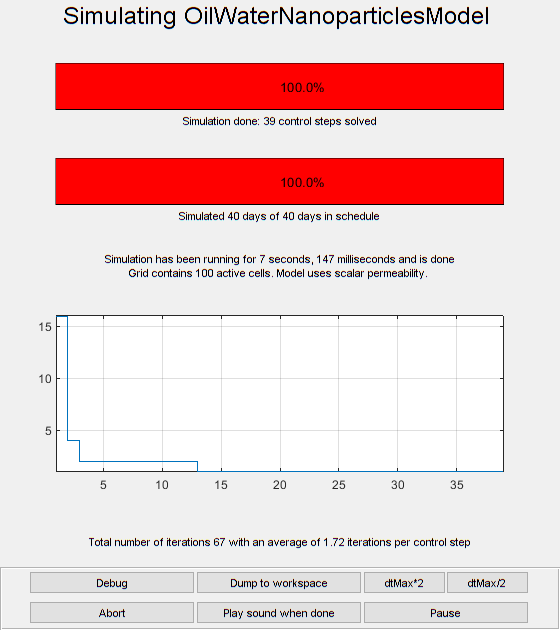

*** Simulation complete. Solved 39 control steps in 7 Seconds, 147 Milliseconds ***


% Run the simulation
[~, statesSurfactant, report] = simulateScheduleAD(state0, model, schedule, ...
                       'NonLinearSolver', solver, 'afterStepFn',fn);

%---------------------------------------------------------------------------------------
% figure()
% plotToolbar(G, statesSurfactant, 'startplayback', true, 'plot1d', true, 'field', 's:1');
y = fluid.pcOW;
disp(y)

    @(s,varargin)b_w.*((s-fluid.krPts.w(1))/(1-fluid.krPts.o(1)-fluid.krPts.o(1))+eps(10)).^-a_w+b_o.*(1-(s-fluid.krPts.w(1))/(1-fluid.krPts.o(1)-fluid.krPts.o(1))+eps(10)).^-a_o



**Plotting the results**

- Set  $Z=\frac{z}{H}$

- Plot $c\ vs\ Z$ ; Fig.1

- Plot $S_w \ vs\ Z$ ; Fig.2

- Plot  $\varphi /\varphi_0 \ vs\ Z$ ; Fig.3

- Plot $\frac{K}{K_0 }\ vs\ Z$ ; Fig.4

- Plot $k_{rw} ,\ k_{ro} \ vs\ S$ ; Fig.5

- Plot $p_c \ vs\ S$ ; Fig.6

% Dimensionless Distance
Z = linespace(0, H, Nz);
Z = z./H;
% Normalized Water Saturation
S_w = statesSurfactant{39,1}.s(:,1);
S = (S_w - fluid.krPts.w(1))/(1 - fluid.krPts.o(1) - fluid.krPts.o(1));
% Ratio of porosity and permeability
phi = statesSurfactant{39,1}.PVTProps.EORPoreVolume;
phi_ratio = phi./model.rock.poro;
K = statesSurfactant{39,1}.PVTProps.AbsolutePermReduction;
K_ratio = K./model.rock.perm;
% Normalized nanoparticles concentration
c = statesSurfactant{39,1}.cs;
C = c./bc.cs(2);
% RelativePermeabilities and capillary pressure
kr_W = statesSurfactant{39,1}.PVTProps.PVTBaseRelativePermeability(:,1);
kr_O = statesSurfactant{39,1}.PVTProps.PVTBaseRelativePermeability(:,2);
pc_OW = statesSurfactant{39,1}.PVTProps.PVTBlackoilCapillaryPressure;
%--------------------------------------------------------------------------------------------
figure()
subplot(2,3,1);
plot(Z,C);
title('C vs Z');

subplot(2,3,2);
plot(Z, S_w);
title('S_w vs Z');

sublot(2,3,3);
plot(Z, phi_ratio);
title('phi_ratio vs Z');

sublot(2,3,4);
plot(Z, K_ratio);
title('K_ratio vs Z');

sublot(2,3,5);
plot(S,pc_OW);
title('pc_OW vs S');

sublot (2,3,6);
plot(S,kr_W,'ro-',kr_O,'bs:');
title('k_r vs S');